**Mini quiz -- Linearization template**

**Data**

x = [10    20    30    40    50    60    70    80    90   100]

x =     10    20    30    40    50    60    70    80    90   100



y = [0.18    0.29    0.32    0.39    0.40    0.41    0.43    0.47    0.47    0.47]

y =     0.1800    0.2900    0.3200    0.3900    0.4000    0.4100    0.4300    0.4700    0.4700    0.4700


**Plot data**

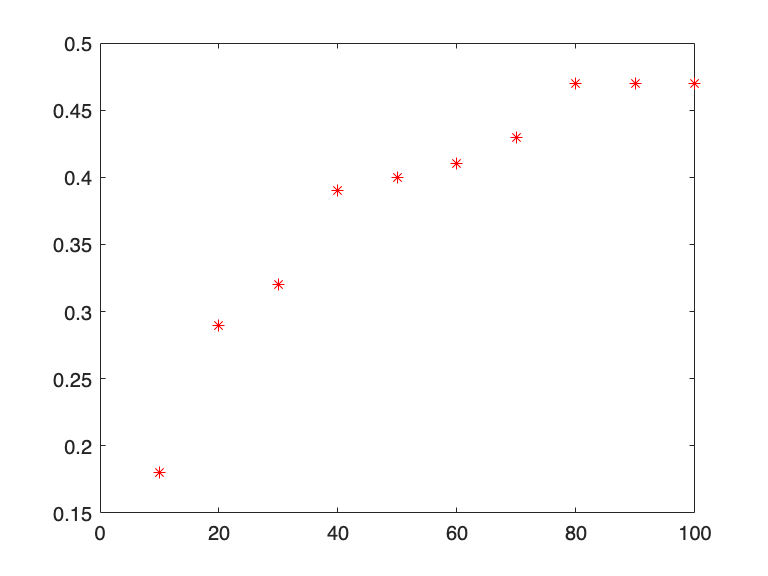

plot(x, y, 'r*')

**Transform data**

new_x = 1 ./ x

new_x =     0.1000    0.0500    0.0333    0.0250    0.0200    0.0167    0.0143    0.0125    0.0111    0.0100


new_y = 1 ./ y

new_y =     5.5556    3.4483    3.1250    2.5641    2.5000    2.4390    2.3256    2.1277    2.1277    2.1277


**Perform linear regression & plot dataset + fitted line**

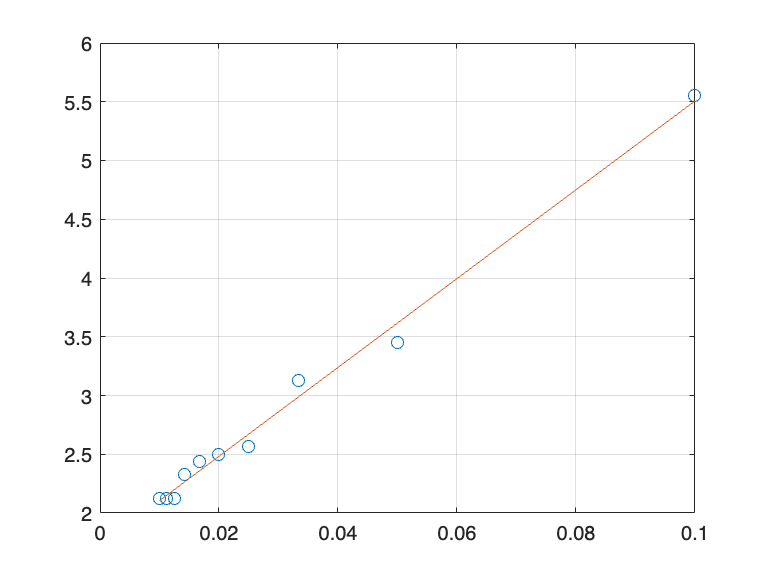

a =    37.8012    1.7269


r2 = 0.9922

[a, r2] = linregr(new_x, new_y)


my_slope = a(1)

my_slope = 37.8012

my_intercept = a(2)

my_intercept = 1.7269

**Computer parameters of nonlinear equation from the fitted line**

alpha = 1/my_intercept

alpha = 0.5791

beta = alpha * my_slope

beta = 21.8901

**Plot the original data with the best fit nonlinear curve**

xp = linspace(min(x), max(x), 100)

xp =    10.0000   10.9091   11.8182   12.7273   13.6364   14.5455   15.4545   16.3636   17.2727   18.1818   19.0909   20.0000   20.9091   21.8182   22.7273   23.6364   24.5455   25.4545   26.3636   27.2727   28.1818   29.0909   30.0000   30.9091   31.8182   32.7273   33.6364   34.5455   35.4545   36.3636   37.2727   38.1818   39.0909   40.0000   40.9091   41.8182   42.7273   43.6364   44.5455   45.4545   46.3636   47.2727   48.1818   49.0909   50.0000   50.9091   51.8182   52.7273   53.6364   54.5455


yp = alpha .* (xp / (beta + xp))

yp = 0.4314

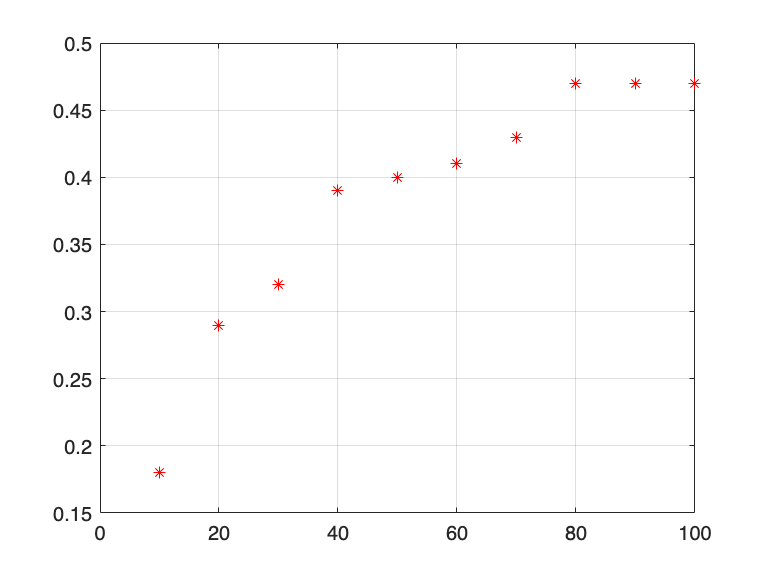


plot(x, y, 'r*', xp, yp)
grid on

**Predict the value of y for the given x**

xtest = 45

xtest = 45

ytest = alpha .* (xtest / (beta + xtest))

ytest = 0.3896